# 粒子群算法解方程(组)

## 核心思想：对于 f(...)=0， 令 |f(...)| 取最小值

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


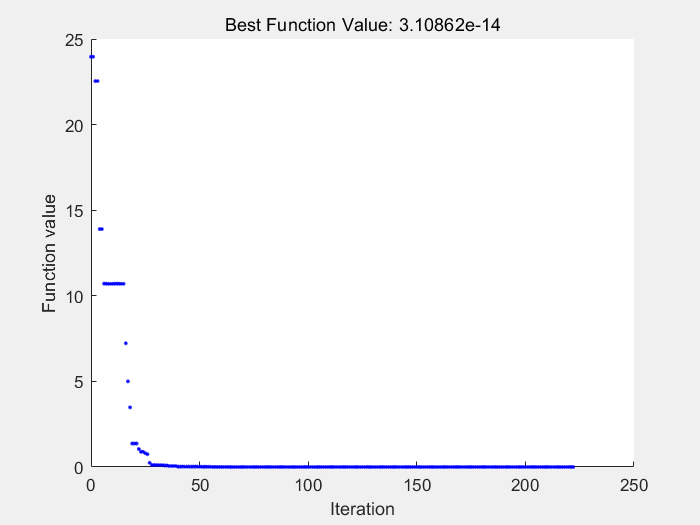

nvars = 3;
x_lb = [-10 -10 -10];
x_ub = [10 10 10];

options = optimoptions("particleswarm","PlotFcn","pswplotbestf","FunctionTolerance",1e-12, ...
    "MaxIterations",1e4);
[x, fval, ~, ~] = particleswarm(@Obj_fun, nvars, x_lb, x_ub, options);

x, fval

x =     1.4206   -4.3401    2.9195


fval = 3.1086e-14

## 定义方程组

function y = Obj_fun(x)
    f1 = abs(x(1)+x(2))-abs(x(3));
    f2 = x(1)*x(2)*x(3) +18;
    f3 = (x(1)^2)*x(2) + 3*x(3);
    y = abs(f1)+abs(f2)+abs(f3);
end